# Initialize


clc;
clear;
close all;

startup;

Loading: E:\ChalmersOnedrive\OneDrive - Chalmers\文档\chalmers\sensor fusion\SensorFusion\project\Sensorfusion smartphone\sensordata.jar


********************
* SensorDataReader started on 192.168.31.220:3401
********************
Connection accepted from 192.168.31.228:43596


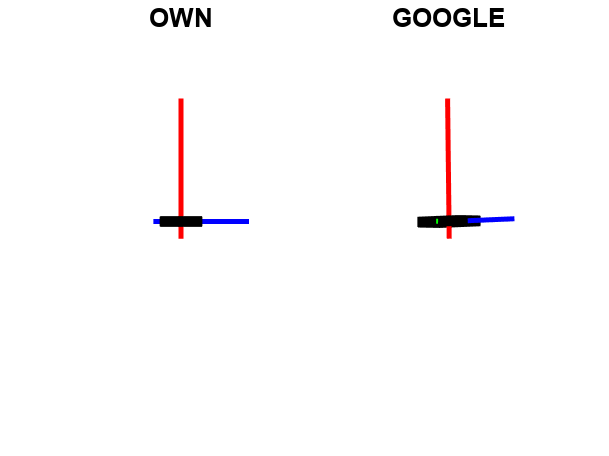

xhat = struct with fields:
    t: [0 0.0100 0.0210 0.0320 0.0415 0.0510 0.0610 0.0707 0.0808 0.0907 0.0990 0.1067 0.1125 0.1190 0.1267 0.1320 0.1387 0.1460 0.1520 0.1580 0.1660 0.1720 0.1777 0.1868 0.1967 0.2062 0.2163 0.2260 0.2360 0.2460 0.2555 0.2655 0.2755 0.2853 0.2952 … ]
    x: [4×5768 double]
    P: [4×4×5768 double]


meas = struct with fields:
         t: [0 0.0100 0.0210 0.0320 0.0415 0.0510 0.0610 0.0707 0.0808 0.0907 0.0990 0.1067 0.1125 0.1190 0.1267 0.1320 0.1387 0.1460 0.1520 0.1580 0.1660 0.1720 0.1777 0.1868 0.1967 0.2062 0.2163 0.2260 0.2360 0.2460 0.2555 0.2655 0.2755 0.2853 … ]
       acc: [3×5768 double]
       gyr: [3×5768 double]
       mag: [3×5768 double]
    orient: [4×5768 double]


% [xhat, meas] = Task5_filterTemplate()
[xhat, meas] = filterTemplate()



% load("placeflat.mat");


## plot


t= meas.t;

% plotRead(meas.acc, t, 'acc',0);
% plotRead(meas.gyr, t, 'gyro',0);
% plotRead(meas.mag, t, 'mag',0)
% plotRead(meas.orient,t, 'orient',1)




## histogram & Gaussian

% % plot acc
plotHistograms(meas.acc, 'acc');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of acc -X is 0.219950 
, the covariance of acc -X is 0.011359  

The mean of acc -Y is -0.028492 
, the covariance of acc -Y is 0.012691 

The mean of acc -Z is 9.863996 
, the covariance of acc -Z is 0.022681 



%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 
% % plot gyro
plotHistograms(meas.gyr, 'gyro');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of gyro -X is -0.000004 
, the covariance of gyro -X is 0.001220  

The mean of gyro -Y is -0.000002 
, the covariance of gyro -Y is 0.000731 

The mean of gyro -Z is 0.000001 
, the covariance of gyro -Z is 0.000493 



%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 
% plot mag
plotHistograms(meas.mag, 'mag');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
The mean of mag -X is -6.187865 
, the covariance of mag -X is 0.353488  

The mean of mag -Y is 17.388269 
, the covariance of mag -Y is 0.382853 

The mean of mag -Z is -56.170076 
, the covariance of mag -Z is 0.584917 



%%%%%%%%%%%%%%%%%%%%%%%%%%%%


close all;



## Task 4

% % omega can just use reading from gyro
% omega = removeNaN(meas.gyr);
% % q can read from orientation
% x = removeNaN(meas.orient);

